clear all
close all
clc

m = ones(1,5);
m1=ones(1,5);
m(1)=100; m(2)=300; m(3)=600; m(4)=1500; m(5)=5000;
n(1)=5; n(2)=10; n(3)=15; n(4)=40; n(5)=90;
P = 1:3:35;
[Pr, Pc] = size(P);
scaleup = ones(Pr, Pc ,5,5);



for k=1:5

    for z=1:5
    
        for i=1:size(P,2)

            K = sqrt(m(z)/2);
            m1(z)=m(z)*P(i);
            K1=sqrt(m1(z)/2);
            time_oneP = m(z) * (3*n(k)*K + K + n(k) + 1) + K*(2+n(k));
            time_multP = m1(z)/P(i) * (3*n(k)*K1 + K1 + n(k) + 1) + K1 * (2*P(i) + n(k));
            scaleup(1,i,z,k) = time_oneP / time_multP;
        
        end
    
    end

end


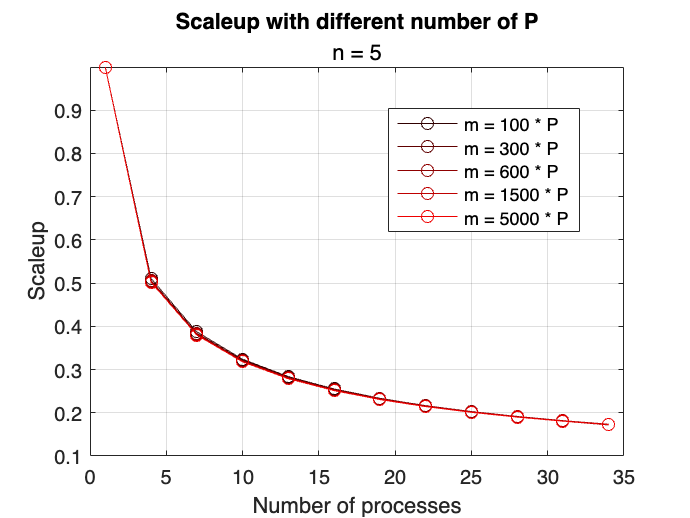

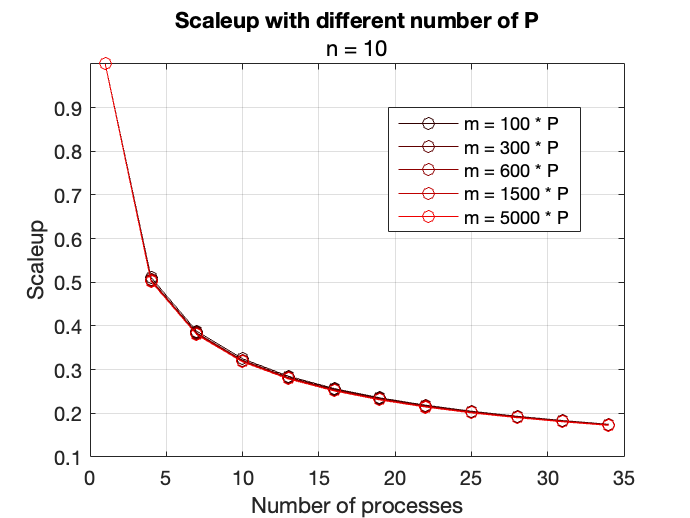

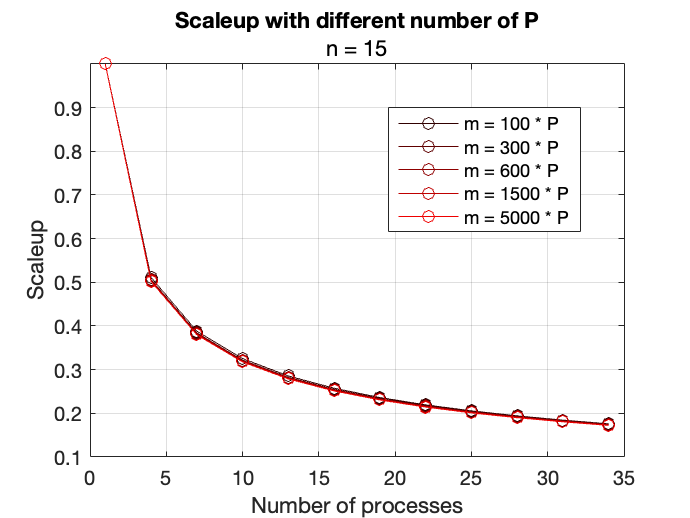

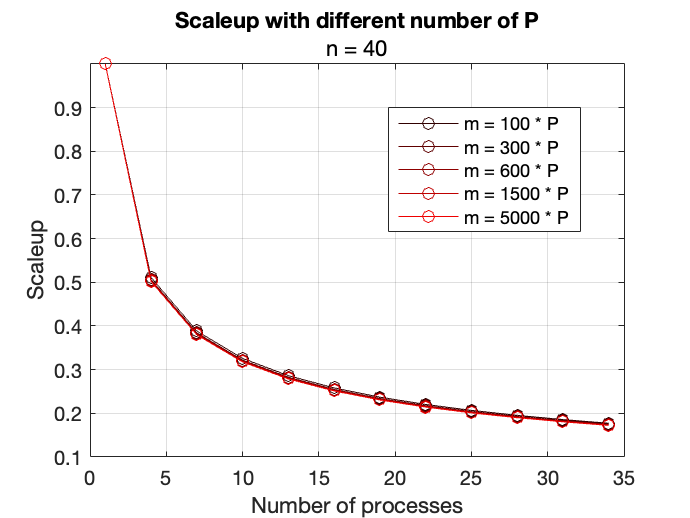

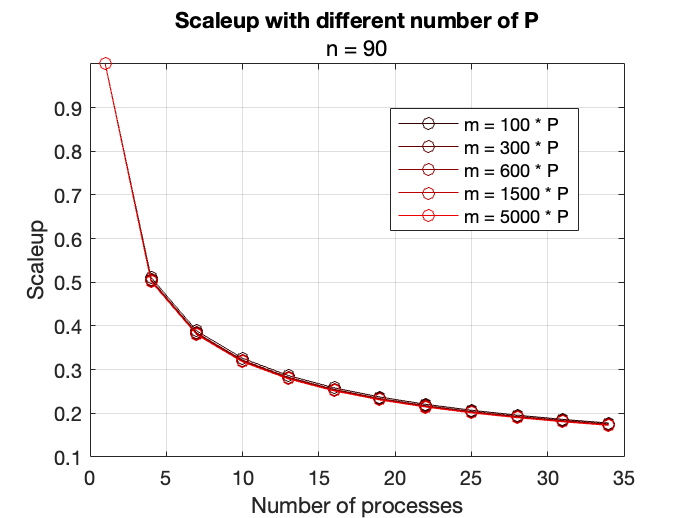

for k=1:5
    for z=1:5
        plot(P,scaleup(1,:,z,k),'b-o',Color=[(z*3)/(5*3+1),0,0]);
        
        hold on
    end
    hold off
    title('Scaleup with different number of P');
    subtitle(sprintf('n = %d', n(k)));
    grid on;
    xlabel('Number of processes');
    ylabel('Scaleup');
    
    legend("Position",[0.56535,0.55365,0.27246,0.23552])
    legend('m = 100 * P', 'm = 300 * P' , 'm = 600 * P', 'm = 1500 * P' , 'm = 5000 * P');
    figure()
    

end